clc; clear all; close all;

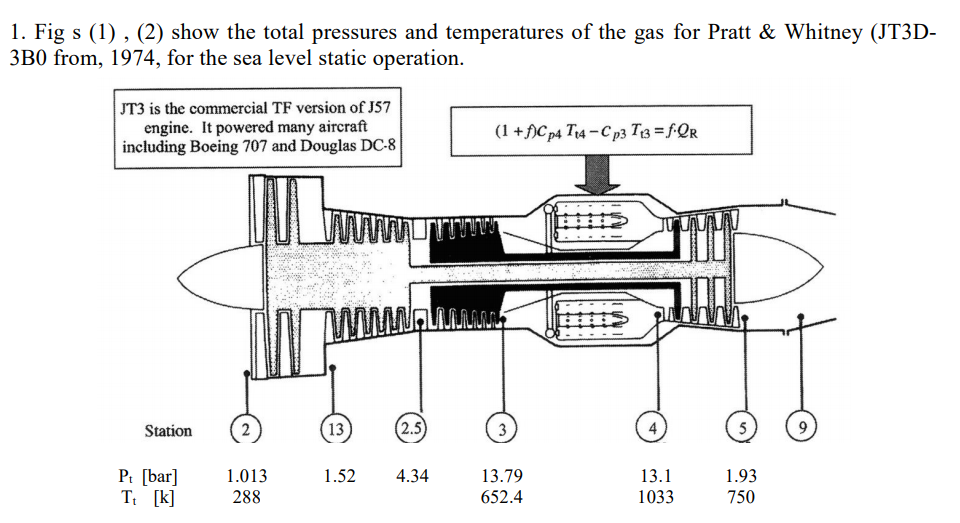

## Data


% Constant Values
Q_R = 2.8*10^7;
P_star_over_p_back=1.893;
gamma_F=1.4;gamma_C=1.4;gamma_T=1.3;gamma_nc=1.3;
R = 287;
e_F =0.86;e_C=0.88;e_T=0;%??? %From Tables 
% Given
Cp_3=1004.5;Cp_4=1088;
m_dot_F=120.2;
m_dot_C=88.45;
Tt_2=288;      Pt_2=1.013;
               Pt_13=1.52;
               Pt_25=4.34;
Tt_3=652.4;    Pt_3=13.79;
Tt_4=1033;     Pt_4=13.1;
Tt_5=750;      Pt_5=1.93;

Pb =1.013; % at flight condition

## ByPass Ratio { alpha }


alpha=m_dot_F/m_dot_C

alpha = 1.3590

## Fuel to air Ratio {f} &  the fuel flow rate { m_dot_f }


f=(Cp_4*Tt_4 - Cp_3*Tt_3)/(Q_R - Cp_4*Tt_4)

f = 0.0174

m_dot_f=f*m_dot_C*60*60 % kg/h

m_dot_f = 5.5515e+03

## Fan, core and total static thrust and compare your answers to the specified thrust


% For Fan {13}
    if Pt_13/Pb < P_star_over_p_back
     disp("UnChoked Fan") 
     M_F_e=(2/(gamma_F-1)*((Pt_13/Pb)^(1-1/gamma_F)-1))^0.5; %must be < 1
     Pi_F=Pt_13/Pt_2;
     Taw_F=Pi_F^(1/e_F-1/gamma_F/e_F);
     Tt_13=Tt_2*Taw_F;
     V_F_e=((2*gamma_F/(gamma_F-1))*R*Tt_13*(1-(Pb/Pt_13)^(1-1/gamma_F)))^0.5;
     F_F=m_dot_F*V_F_e
    else
     % ????????????
    end

UnChoked Fan


F_F = 3.2361e+04

%For Core LPC {13:2.5}   %% why 13 ??!! not 2
  Pi_LPC=Pt_25/Pt_13;
  Taw_LPC=Pi_LPC^(1/e_C-1/gamma_C/e_C);
  Tt_25=Tt_13*Taw_LPC;
%For Core HPC {2.5:3}
  Pi_HPC=Pt_3/Pt_25;
  Taw_HPC=Pi_HPC^(1/e_C-1/gamma_C/e_C);
%   Tt_3=Tt_25*Taw_HPC
%For Core Fan {5:9}
   if Pt_5/Pb < P_star_over_p_back
       
   else
     disp("Choked Core") 
     M_C_e=1;
     Tt_9= Tt_5;
     T_9=Tt_9/(gamma_nc/2+1/2);
     V_C_e=(gamma_nc*R*T_9)^0.5;
     F_C=(1+f)*m_dot_C*V_C_e
   end

Choked Core


F_C = 4.4391e+04

%Total Force
F=(F_F+F_C)/1000  %kN

F = 76.7521

## Effective jet velocity, specific thrust

V_C_e

V_C_e = 493.2809

ST=F*1000/(m_dot_C+m_dot_F)

ST = 367.8508

## Thermal efficiency

eta_th=(m_dot_F*V_F_e^2+m_dot_C*V_C_e^2)/(2*m_dot_f/60/60*Q_R)*100

eta_th = 35.0114

## Engine thrust specific fuel consumption

S =m_dot_f/F %mg/N.s

S = 72.3297

## Fan and core nozzles exit Mach number

M_F_e

M_F_e = 0.7840

M_C_e

M_C_e = 1